clc

clear all

Here we show the classification results using SMOTE and Random undersampling as well as SVM vs BiLSTM

The metrics considered are Class specific F-measures, macro average and micro average F-measure, precision, specificity, sensitivity etc. We have also included accuracy even though it may not be a good metric for testing imbalanced dataset. In addition normalized confusion matrix is also provided for analysis.

## **SVM based Classification**

**REM vs Wake**

Model trained using Random Undersampling of Majority class (The models considered here are the best models obtained using hyperparameter optimization)


Model = load('C:\courses\ML\project\SVM_2_class\trained_model_SVM_US.mat'); % Model trained with Undersampling
Model = Model.model;
Testing = load('C:\courses\ML\project\SVM_2_class\Testingred_features_SVM_US.mat');
Testing = Testing.testFeatures1;
TestingLabels = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\TwoclassTestUSLabels.mat');
TestingLabels = TestingLabels.TwoClassTest_US_Labels';
[label,score] = predict(Model,Testing);
C = confusionmat(TestingLabels,categorical(label));
[stats] = statsOfMeasure(C, 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"        2385        716     1550.5      1550.5 
    "false_positive"        113        878      495.5       495.5 
    "false_negative"        878        113      495.5       495.5 
    "true_negative"         716       2385     1550.5      1550.5 
    "precision"         0.95476    0.44918    0.70197     0.75782 
    "sensitivity"       0.73092    0.86369    0.79731     0.75782 
    "specificity"       0.86369    0.73092    0.79731     0.75782 
    "accuracy"          0.75782    0.75782    0.75782     0.75782 
    "F-measure"         0.82798      0.591    0.70949     0.75782 


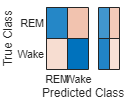

figure
confusionchart(TestingLabels,categorical(label),'Normalization','row-normalized','RowSummary','row-normalized')

Model trained using SMOTE (The models considered here are the best models obtained using hyperparameter optimization)


Model = load('C:\courses\ML\project\SVM_2_class\trained_model_SVM_SMOTE.mat'); % Model trained with Undersampling
Model = Model.model;
Testing = load('C:\courses\ML\project\SVM_2_class\Testingred_features_SVM_SMOTE.mat');
Testing = Testing.testFeatures1;
TestingLabels = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\TwoclassTestSMOTELabels.mat');
TestingLabels = TestingLabels.TwoClassTest_SMOTE_Labels';
[label,score] = predict(Model,Testing);
C = confusionmat(TestingLabels,categorical(label));
[stats] = statsOfMeasure(C, 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"        2927        605       1766        1766 
    "false_positive"        224        336        280         280 
    "false_negative"        336        224        280         280 
    "true_negative"         605       2927       1766        1766 
    "precision"         0.92891    0.64293    0.78592     0.86315 
    "sensitivity"       0.89703    0.72979    0.81341     0.86315 
    "specificity"       0.72979    0.89703    0.81341     0.86315 
    "accuracy"          0.86315    0.86315    0.86315     0.86315 
    "F-measure"         0.91269    0.68362    0.79815     0.86315 


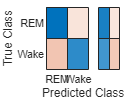

figure
confusionchart(TestingLabels,categorical(label),'Normalization','row-normalized','RowSummary','row-normalized')

**NREM vs Wake**

Model trained using Random Undersampling of Majority class (The models considered here are the best models obtained using hyperparameter optimization)

Model = load('C:\courses\ML\project\SVM_3_class\trained_model_SVM_US.mat'); % Model trained with Undersampling
Model = Model.model;
Testing = load('C:\courses\ML\project\SVM_3_class\Testingred_features_SVM_US.mat');
Testing = Testing.testFeatures1;
TestingLabels = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\ThreeclassTestUSLabels.mat');
TestingLabels = TestingLabels.ThreeClassTest_US_Labels';
[label,score] = predict(Model,Testing);
C = confusionmat(TestingLabels,categorical(label));
[stats] = statsOfMeasure(C, 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"       13184        716       6950        6950 
    "false_positive"        113       2076     1094.5      1094.5 
    "false_negative"       2076        113     1094.5      1094.5 
    "true_negative"         716      13184       6950        6950 
    "precision"          0.9915    0.25645    0.62397     0.86394 
    "sensitivity"       0.86396    0.86369    0.86382     0.86394 
    "specificity"       0.86369    0.86396    0.86382     0.86394 
    "accuracy"          0.86394    0.86394    0.86394     0.86394 
    "F-measure"         0.92335    0.39547    0.65941     0.86394 


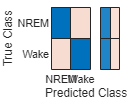

figure
confusionchart(TestingLabels,categorical(label),'Normalization','row-normalized','RowSummary','row-normalized')

Model trained using SMOTE (The models considered here are the best models obtained using hyperparameter optimization)

Model = load('C:\courses\ML\project\SVM_3_class\trained_model_SVM_SMOTE.mat'); % Model trained with SMOTE
Model = Model.model;
Testing = load('C:\courses\ML\project\SVM_3_class\Testingred_features_SVM_SMOTE.mat');
Testing = Testing.testFeatures1;
TestingLabels = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\ThreeclassTestSMOTELabels.mat');
TestingLabels = TestingLabels.ThreeClassTest_SMOTE_Labels';
[label,score] = predict(Model,Testing);
C = confusionmat(TestingLabels,categorical(label));
[stats] = statsOfMeasure(C, 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"       13780        632       7206        7206 
    "false_positive"        197       1480      838.5       838.5 
    "false_negative"       1480        197      838.5       838.5 
    "true_negative"         632      13780       7206        7206 
    "precision"         0.98591    0.29924    0.64257     0.89577 
    "sensitivity"       0.90301    0.76236    0.83269     0.89577 
    "specificity"       0.76236    0.90301    0.83269     0.89577 
    "accuracy"          0.89577    0.89577    0.89577     0.89577 
    "F-measure"         0.94264    0.42979    0.68621     0.89577 


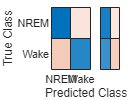

figure
confusionchart(TestingLabels,categorical(label),'Normalization','row-normalized','RowSummary','row-normalized')

**Five class Classification**

Model = load('C:\courses\ML\project\SVM_5_class\AUTOMATEDCODE\trained_model_SVM_US.mat'); % Model trained with Undersampling
Model = Model.model;
Testing = load('C:\courses\ML\project\SVM_5_class\AUTOMATEDCODE\Testingred_features_SVM_US.mat');
Testing = Testing.testFeatures1;
TestingLabels = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\FiveclassTestingUSLabels.mat');
TestingLabels = TestingLabels.Class_Testing';
[label,score] = predict(Model,Testing);
C = confusionmat(TestingLabels,categorical(label));
[stats] = statsOfMeasure(C, 1);

stats = 9×4 table
          name                                     classes                               macroAVG    microAVG
    ________________    _____________________________________________________________    ________    ________

    "true_positive"            12         3936          647          267          628       1098        1098 
    "false_positive"         2453         2055         5256          565         3533     2772.4      2772.4 
    "false_negative"         1362         6077         3226         2996          201     2772.4      2772.4 
    "true_negative"         15525         7284        10223        15524        14990      12709       12709 
    "precision"         0.0048682      0.65699      0.10961      0.32091      0.15093    0.24866     0.28369 
    "sensitivity"       0.0087336      0.39309      0.16705     0.081827   

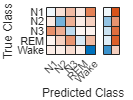

figure
confusionchart(TestingLabels,categorical(label),'Normalization','row-normalized','RowSummary','row-normalized')

## Bidirectional Long Short Term Memory (BiLSTM) based classification

**REM vs Wake**

Model trained using Random Undersampling of Majority class (The models considered here are the best models obtained using hyperparameter optimization)


Model = load('C:\courses\ML\project\codes\TrainNetworkProject2\BiLSTM_fiveclass\hyperparameter_tuning_US_2class\0.22867.mat'); % Best Model trained with Undersampling
Model = Model.netLSTM;
Testing = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\TwoclassTestUS.mat');
Testing = Testing.Balancedsleep2ClasstestUSCell;
TestingLabels = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\TwoclassTestUSLabels.mat');
TestingLabels = TestingLabels.TwoClassTest_US_Labels';
[label,score] = classify(Model,Testing)

label = 4092×1 categorical array
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     Wake 
     Wake 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     Wake 
     REM 
     REM 
     REM 
     REM 
     REM 
     Wake 
     REM 
     REM 


score = 4092×2 single matrix
    0.9400    0.0600
    0.9822    0.0178
    0.8458    0.1542
    0.9981    0.0019
    0.9988    0.0012
    0.9978    0.0022
    0.0114    0.9886
    0.0762    0.9238
    0.9956    0.0044
    0.9952    0.0048


C = confusionmat(TestingLabels,categorical(label));
[stats] = statsOfMeasure(C, 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"        2835        522     1678.5      1678.5 
    "false_positive"        307        428      367.5       367.5 
    "false_negative"        428        307      367.5       367.5 
    "true_negative"         522       2835     1678.5      1678.5 
    "precision"         0.90229    0.54947    0.72588     0.82038 
    "sensitivity"       0.86883    0.62967    0.74925     0.82038 
    "specificity"       0.62967    0.86883    0.74925     0.82038 
    "accuracy"          0.82038    0.82038    0.82038     0.82038 
    "F-measure"         0.88525    0.58685    0.73605     0.82038 


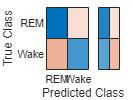

figure
confusionchart(TestingLabels,categorical(label),'Normalization','row-normalized','RowSummary','row-normalized')

Model trained using SMOTE (The models considered here are the best models obtained using hyperparameter optimization)

Model = load('D:\ML\hyperparametertuning_SMOTE_BILSTM_2CLASS\0.22749.mat'); % Best Model trained with SMOTE

Model = Model.netLSTM;
Testing = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\TwoclassTestSMOTE.mat');
Testing = Testing.Balancedsleep2ClasstestSMOTECell;
TestingLabels = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\TwoclassTestSMOTELabels.mat');
TestingLabels = TestingLabels.TwoClassTest_SMOTE_Labels';
[label,score] = classify(Model,Testing)

label = 4092×1 categorical array
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     Wake 
     Wake 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     REM 
     Wake 
     REM 
     REM 


score = 4092×2 single matrix
    0.9557    0.0443
    0.9990    0.0010
    0.9346    0.0654
    0.9931    0.0069
    0.9985    0.0015
    0.9686    0.0314
    0.0968    0.9032
    0.0771    0.9229
    0.9849    0.0151
    0.9945    0.0055


C = confusionmat(TestingLabels,categorical(label));
[stats] = statsOfMeasure(C, 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"        3006        505     1755.5      1755.5 
    "false_positive"        324        257      290.5       290.5 
    "false_negative"        257        324      290.5       290.5 
    "true_negative"         505       3006     1755.5      1755.5 
    "precision"          0.9027    0.66273    0.78272     0.85802 
    "sensitivity"       0.92124    0.60917     0.7652     0.85802 
    "specificity"       0.60917    0.92124     0.7652     0.85802 
    "accuracy"          0.85802    0.85802    0.85802     0.85802 
    "F-measure"         0.91188    0.63482    0.77335     0.85802 


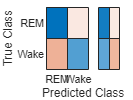

figure
confusionchart(TestingLabels,categorical(label),'Normalization','row-normalized','RowSummary','row-normalized')

**NREM vs Wake**

Model trained using Random Undersampling of Majority class (The models considered here are the best models obtained using hyperparameter optimization)


Model = load('C:\courses\ML\project\codes\TrainNetworkProject2\BiLSTM_fiveclass\Hyperparameter_tuning_US_3Class\0.244.mat'); % Model trained with Undersampling
Model = Model.netLSTM;
Testing = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\ThreeclassTestUS.mat');
Testing = Testing.Balancedsleep3ClasstestUSCell;
TestingLabels = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\ThreeclassTestUSLabels.mat');
TestingLabels = TestingLabels.ThreeClassTest_US_Labels';
[label,score] = classify(Model,Testing)

label = 16089×1 categorical array
     NREM 
     Wake 
     Wake 
     Wake 
     NREM 
     NREM 
     NREM 
     Wake 
     NREM 
     Wake 
     Wake 
     Wake 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     Wake 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 


score = 16089×2 single matrix
    0.7407    0.2593
    0.0128    0.9872
    0.2245    0.7755
    0.2174    0.7826
    0.7075    0.2925
    0.6582    0.3418
    0.5454    0.4546
    0.4442    0.5558
    0.7784    0.2216
    0.2841    0.7159


C = confusionmat(TestingLabels,categorical(label));
[stats] = statsOfMeasure(C, 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"       13295        493       6894        6894 
    "false_positive"        336       1965     1150.5      1150.5 
    "false_negative"       1965        336     1150.5      1150.5 
    "true_negative"         493      13295       6894        6894 
    "precision"         0.97535    0.20057    0.58796     0.85698 
    "sensitivity"       0.87123    0.59469    0.73296     0.85698 
    "specificity"       0.59469    0.87123    0.73296     0.85698 
    "accuracy"          0.85698    0.85698    0.85698     0.85698 
    "F-measure"         0.92036    0.29997    0.61016     0.85698 


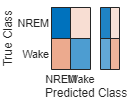

figure
confusionchart(TestingLabels,categorical(label),'Normalization','row-normalized','RowSummary','row-normalized')

Model trained using SMOTE (The models considered here are the best models obtained using hyperparameter optimization)

Model = load('C:\courses\ML\project\codes\TrainNetworkProject2\BiLSTM_fiveclass\Hyperparameter_tuning_SMOTE_3class\0.21382.mat'); % Best Model trained with SMOTE
Model = Model.netLSTM;
Testing = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\ThreeclassTestSMOTE.mat');
Testing = Testing.Balancedsleep3ClasstestSMOTECell;
TestingLabels = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\ThreeclassTestSMOTELabels.mat');
TestingLabels = TestingLabels.ThreeClassTest_SMOTE_Labels';
[label,score] = classify(Model,Testing)

label = 16089×1 categorical array
     NREM 
     Wake 
     NREM 
     NREM 
     NREM 
     NREM 
     Wake 
     NREM 
     NREM 
     Wake 
     Wake 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 
     NREM 


score = 16089×2 single matrix
    0.7798    0.2202
    0.3349    0.6651
    0.6163    0.3837
    0.6663    0.3337
    0.6256    0.3744
    0.8045    0.1955
    0.1394    0.8606
    0.6510    0.3490
    0.8357    0.1643
    0.3852    0.6148


C = confusionmat(TestingLabels,categorical(label));
[stats] = statsOfMeasure(C, 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"       14366        419     7392.5      7392.5 
    "false_positive"        410        894        652         652 
    "false_negative"        894        410        652         652 
    "true_negative"         419      14366     7392.5      7392.5 
    "precision"         0.97225    0.31912    0.64568     0.91895 
    "sensitivity"       0.94142    0.50543    0.72342     0.91895 
    "specificity"       0.50543    0.94142    0.72342     0.91895 
    "accuracy"          0.91895    0.91895    0.91895     0.91895 
    "F-measure"         0.95659    0.39122     0.6739     0.91895 


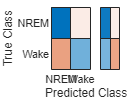

figure
confusionchart(TestingLabels,categorical(label),'Normalization','row-normalized','RowSummary','row-normalized')

**Five Class classification**

Model trained using Random Undersampling of Majority class (The models considered here are the best models obtained using hyperparameter optimization)


Model = load('C:\courses\ML\project\codes\TrainNetworkProject2\BiLSTM_fiveclass\HYPERPARAMETER_TUNING_US_5class\0.5248.mat'); % Model trained with Undersampling
Model = Model.netLSTM;
Testing = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\FiveclassTestingUS.mat');
Testing = Testing.BalancedsleepDataTestingCell;
TestingLabels = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\FiveclassTestingUSLabels.mat');
TestingLabels = TestingLabels.Class_Testing';
[label,score] = classify(Model,Testing)

label = 19352×1 categorical array
     Wake 
     Wake 
     Wake 
     N2 
     N2 
     N3 
     Wake 
     N2 
     N3 
     Wake 
     Wake 
     REM 
     REM 
     N2 
     N2 
     N2 
     N2 
     N3 
     REM 
     N1 
     REM 
     REM 
     REM 
     N3 
     N2 
     N3 
     N2 
     REM 
     N3 
     N3 


score = 19352×5 single matrix
    0.0295    0.1163    0.1966    0.0041    0.6535
    0.0530    0.0839    0.2921    0.2769    0.2941
    0.1144    0.0664    0.2754    0.0247    0.5191
    0.1395    0.3937    0.2566    0.1097    0.1004
    0.0223    0.4391    0.3134    0.0291    0.1961
    0.0536    0.3070    0.4888    0.0843    0.0663
    0.1298    0.1992    0.0520    0.2576    0.3614
    0.1285    0.4375    0.0928    0.2532    0.0880
    0.1092    0.2144    0.3630    0.1461    0.1673
    0.0882    0.1299    0.0548    0.1778    0.5493


C = confusionmat(TestingLabels,categorical(label));
[stats] = statsOfMeasure(C, 1);

stats = 9×4 table
          name                                  classes                             macroAVG    microAVG
    ________________    ________________________________________________________    ________    ________

    "true_positive"          125        3735        3176        1445         309       1758        1758 
    "false_positive"        1089        2034        3448        3280         711     2112.4      2112.4 
    "false_negative"        1249        6278         697        1818         520     2112.4      2112.4 
    "true_negative"        16889        7305       12031       12809       17812      13369       13369 
    "precision"          0.10297     0.64743     0.47947     0.30582     0.30294    0.36772     0.45422 
    "sensitivity"       0.090975     0.37302     0.82004     0.44284     0.37274    0.41992     0.45422 
    "

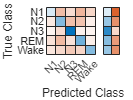

figure
confusionchart(TestingLabels,categorical(label),'Normalization','row-normalized','RowSummary','row-normalized')

Model trained using SMOTE (The models considered here are the best models obtained using hyperparameter optimization)

Model = load('C:\courses\ML\project\codes\TrainNetworkProject2\BiLSTM_fiveclass\trainedModels_hyperparametertuning_SMOTE5CLASS\0.65897.mat'); % Best Model trained with SMOTE
Model = Model.netLSTM;
Testing = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\FiveclassTestingSMOTE.mat');
Testing = Testing.BalancedsleepDataTestingSMOTECell;
TestingLabels = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\FiveclassTestingSMOTELabels.mat');
TestingLabels = TestingLabels.Class_TestingSMOTE';
[label,score] = classify(Model,Testing)

label = 19352×1 categorical array
     N1 
     N2 
     N1 
     N2 
     N1 
     N2 
     REM 
     N2 
     REM 
     Wake 
     Wake 
     REM 
     N2 
     REM 
     N2 
     REM 
     N2 
     N1 
     N2 
     N2 
     REM 
     N1 
     N2 
     N2 
     N2 
     N1 
     N2 
     N2 
     N1 
     N2 


score = 19352×5 single matrix
    0.6301    0.2694    0.0017    0.0023    0.0965
    0.1846    0.6457    0.0057    0.0949    0.0692
    0.5772    0.2275    0.0625    0.0191    0.1137
    0.2231    0.6506    0.0178    0.0407    0.0679
    0.4869    0.2097    0.0240    0.0076    0.2719
    0.4082    0.4418    0.0015    0.0039    0.1447
    0.0196    0.1478    0.0370    0.4203    0.3754
    0.1025    0.4102    0.1385    0.1919    0.1570
    0.1044    0.2867    0.1724    0.3084    0.1281
    0.0692    0.1869    0.1244    0.1528    0.4667


C = confusionmat(TestingLabels,categorical(label));
[stats] = statsOfMeasure(C, 1);

stats = 9×4 table
          name                                    classes                               macroAVG    microAVG
    ________________    ____________________________________________________________    ________    ________

    "true_positive"           90         5862            7         1415          309     1536.6      1536.6 
    "false_positive"        5245         2635          832         2386          571     2333.8      2333.8 
    "false_negative"        1284         4151         3866         1848          520     2333.8      2333.8 
    "true_negative"        12733         6704        14647        13703        17952      13148       13148 
    "precision"          0.01687      0.68989    0.0083433      0.37227      0.35114     0.2877     0.39701 
    "sensitivity"       0.065502      0.58544    0.0018074      0.43365      0.372

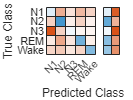

figure
confusionchart(TestingLabels,categorical(label),'Normalization','row-normalized','RowSummary','row-normalized')